3 ways to define a transfer function: tf('s'), tf(num, den), zpk()

% 1. define transfer function
s = tf('s');

GH = 1/(s*(s+4)*(s^2+4*s+20))


GH =
 
               1
  ---------------------------
  s^4 + 8 s^3 + 36 s^2 + 80 s
 
Continuous-time transfer function.



% essentially defined k=1, but can see different results by mult. by a gain
k=2

k = 2

GH*k


ans =
 
               2
  ---------------------------
  s^4 + 8 s^3 + 36 s^2 + 80 s
 
Continuous-time transfer function.



% 2. could also define transfer function using tf
num = 1;
den = [1 8 36 80 0]

den =      1     8    36    80     0


GH = tf(num, den) % gives same result but requires multiplying out to get coefficients


GH =
 
               1
  ---------------------------
  s^4 + 8 s^3 + 36 s^2 + 80 s
 
Continuous-time transfer function.



% 3. use zeros, poles, k function to build it
GH = zpk([], [0, -4, -2+4i, -2-4i], 1)


GH =
 
             1
  -----------------------
  s (s+4) (s^2 + 4s + 20)
 
Continuous-time zero/pole/gain model.


Find the poles and zeros of the system

p = pole(GH) % find poles (there are 4)

p =    0.0000 + 0.0000i
  -4.0000 + 0.0000i
  -2.0000 + 4.0000i
  -2.0000 - 4.0000i



% alternatively, pass in coefficients to roots function
r = roots([1 8 36 80 0])

r =    0.0000 + 0.0000i
  -2.0000 + 4.0000i
  -2.0000 - 4.0000i
  -4.0000 + 0.0000i



z = zero(GH) % find zeros (there aren't any)


z =

  0×1 empty double column vector



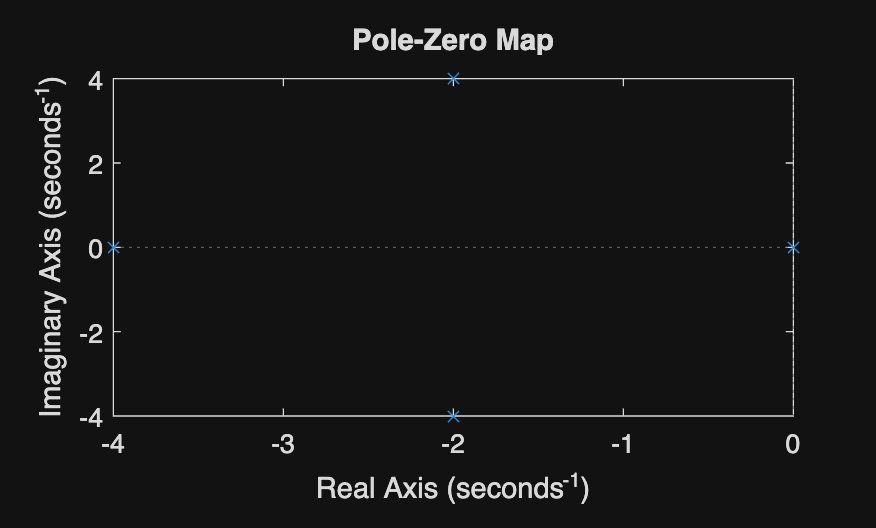


% alternatively, visually see poles and zeros using pzmap
pzmap(GH) % shows open loop poles from GH in feed forward loop

Find the root locus of G(s)H(s) = k / s(s+4)(s^2+4s+20)

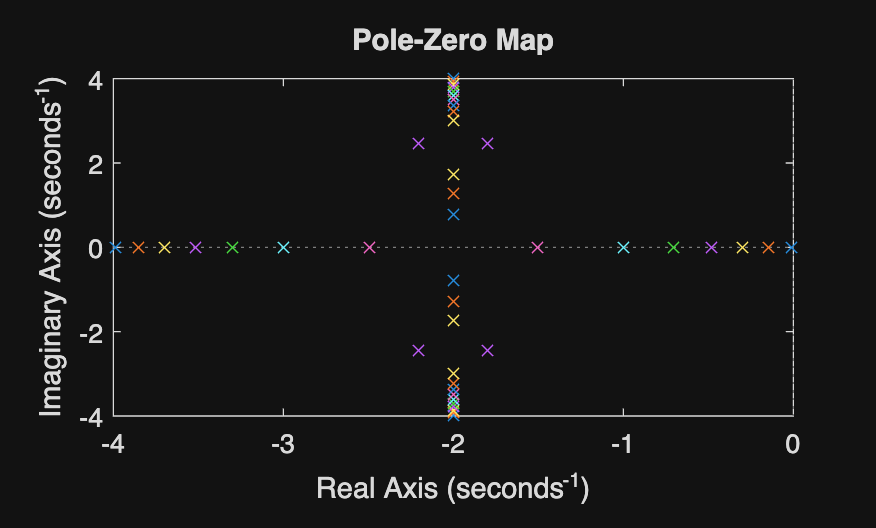

% manual for loop method: plot a bunch of points
for k=1:10:101
pzmap(feedback(k*GH, 1)) % assume GH is forward TF, and multiply by gain k. 1 for unity feedback
hold on % keep plot on while running the loop
end

%
hold off 

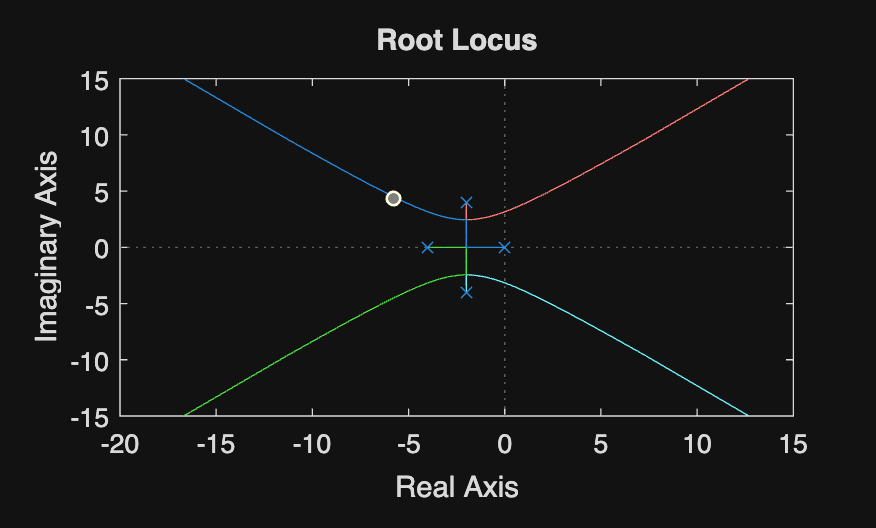

rlocus(GH)


% add a gain marker to see what value of k it would take to place a root at
% a certain point -> use the figure popup window to see when the syst
% would go unstable or reach a certain zeta

% use control system designer (siso) 
